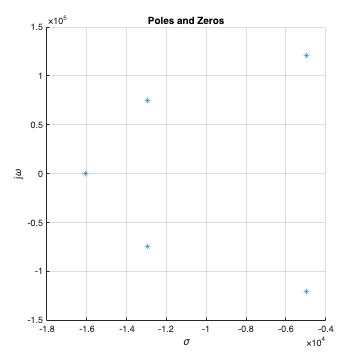

clear 
close all
clc
N = 5;
Wp = 2*pi*20e3;
Rp = 5;
[num, den] = cheby1(N, Rp, Wp, 'low', 's');
[z, p, k] = cheby1(N, Rp, Wp, 'low', 's');


% Poles and Zeros
figure('Position',[400 600 400 400]);
figure(1)
plot(z,'o');
hold on
plot(p,'*');
title("Poles and Zeros");
ylabel("j\omega");
xlabel("\sigma");
grid on

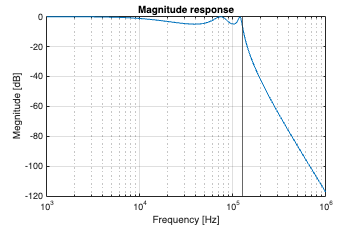


T = tf(num, den);
[H, w] = freqs(num, den);
% Magnitude response
figure('Position',[900 750 400 250]);
figure(2);
semilogx(w, 20*log10(abs(H)));
grid on
title("Magnitude response");
ylabel("Megnitude [dB]");
xlabel("Frequency [Hz]");
xline(2*pi*20e3);

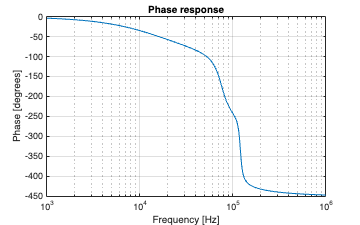

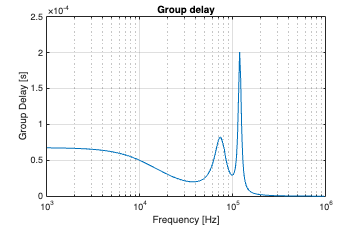


% Phase response
figure('Position',[900 400 400 250]);
figure(3);
% semilogx(w, 180/pi*phase(H));
semilogx(w, 180/pi*unwrap(angle(H)));
title("Phase response");
ylabel("Phase [degrees]");
xlabel("Frequency [Hz]");
grid on

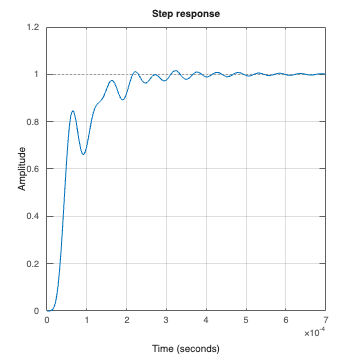


% Step response
figure('Position',[400 50 400 400]);
figure(5)
step(T)
title("Step response");
grid on